%% ============================================================
% MAS ASSIGNMENT 3
% Sequential Multi-Agent Formation Control
%
% Name              : ADITYA
% Number of Agents  : N = 20
% State Space       : R^2
% Graph             : Connected Erdos-Renyi G(N,p)
%
% Formation sequence:
% Random -> A -> D -> I -> T -> Y -> A
%
% OUTPUT FILES:
%   ADITYA_formation.mp4
%   communication_graph.png
%   formation_error.png
%
% =============================================================

clear;
clc;
close all;

%% ============================================================
% 1. PARAMETERS
% ============================================================

N = 20;                  % Number of agents

p = 0.25;                % Erdos-Renyi connection probability

kf = 2.0;                % Formation attraction gain
kc = 0.5;                % Communication gain

dt = 0.05;               % Simulation time step

T_initial = 2;           % Time to move from random positions

T_letter = 2.5;          % Time for each letter

videoFPS = 15;           % Video frame rate

% Record every few simulation steps
recordEvery = 2;

NAME = 'ADITYA';

% Reproducible random numbers
rng(10);


%% ============================================================
% 2. GENERATE CONNECTED ERDOS-RENYI GRAPH
% ============================================================

fprintf('\n');
fprintf('============================================\n');

fprintf(' MAS ASSIGNMENT 3 - ADITYA\n');

 MAS ASSIGNMENT 3 - ADITYA


fprintf('============================================\n');


fprintf('Generating connected Erdos-Renyi graph...\n');

Generating connected Erdos-Renyi graph...



connected = false;

while ~connected

    % Random graph
    A = rand(N,N) < p;

    % Make graph undirected
    A = triu(A,1);
    A = A + A';

    % Create MATLAB graph
    G = graph(A);

    % Check connectivity
    components = conncomp(G);

    if max(components) == 1
        connected = true;
    end

end

numberOfEdges = nnz(A)/2;

fprintf('Graph generated successfully.\n');

Graph generated successfully.


fprintf('Number of agents : %d\n',N);

Number of agents : 20


fprintf('Probability p    : %.2f\n',p);

Probability p    : 0.25


fprintf('Number of edges  : %d\n',numberOfEdges);

Number of edges  : 48


fprintf('Graph connected  : YES\n');

Graph connected  : YES


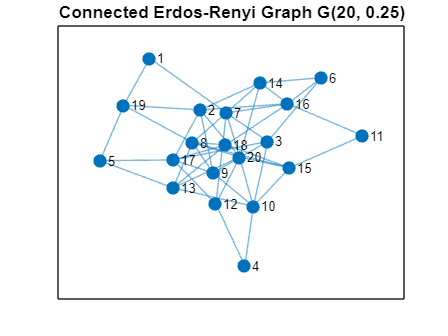



%% ============================================================
% 3. DISPLAY AND SAVE COMMUNICATION GRAPH
% ============================================================

figGraph = figure(...
    'Color','w',...
    'Name','Erdos-Renyi Communication Graph');

plot(G,...
    'Layout','force',...
    'NodeLabel',1:N,...
    'MarkerSize',7);

title(sprintf(...
    'Connected Erdos-Renyi Graph G(%d, %.2f)',N,p));

saveas(figGraph,'communication_graph.png');



%% ============================================================
% 4. RANDOM INITIAL POSITIONS
% ============================================================

% Random positions in R^2
x = 8*rand(N,2)-4;

initialPosition = x;


%% ============================================================
% 5. CREATE LETTER FORMATIONS
% ============================================================

letters = upper(NAME);

numLetters = length(letters);

formations = cell(numLetters,1);

fprintf('\nCreating formations:\n');


Creating formations:



for i = 1:numLetters

    formations{i} = createLetter(...
        letters(i),N);

    fprintf('%s ',letters(i));

end

A D I T Y A 


fprintf('\n');


%% ============================================================
% 6. CREATE VIDEO
% ============================================================

fprintf('\nCreating video...\n');


Creating video...



video = VideoWriter(...
    'ADITYA_formation.mp4',...
    'MPEG-4');

video.FrameRate = videoFPS;
video.Quality = 85;

open(video);


%% ============================================================
% 7. CREATE MAIN FIGURE
% ============================================================

fig = figure(...
    'Color','w',...
    'Name','MAS Formation Control',...
    'NumberTitle','off',...
    'Position',[100 100 900 700]);


%% ============================================================
% 8. DATA FOR FORMATION ERROR
% ============================================================

errorHistory = [];
timeHistory = [];

simulationTime = 0;

frameCounter = 0;


%% ============================================================
% 9. INITIAL RANDOM POSITION -> A
% ============================================================

target = formations{1};

initialSteps = round(T_initial/dt);

fprintf('\nInitial movement: Random -> A\n');


Initial movement: Random -> A


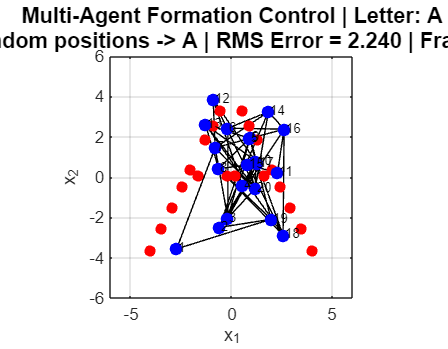

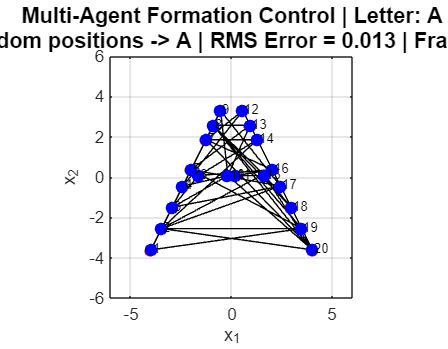


for k = 1:initialSteps

    % Distributed formation control
    x = formationController(...
        x,...
        target,...
        A,...
        kf,...
        kc,...
        dt);

    simulationTime = simulationTime + dt;

    % Formation error
    currentError = sqrt(...
        mean(sum((x-target).^2,2)));

    errorHistory(end+1) = currentError;
    timeHistory(end+1) = simulationTime;


    % Record only selected frames
    if mod(k,recordEvery) == 0

        frameCounter = frameCounter + 1;

        drawFormation(...
            x,...
            target,...
            A,...
            'A',...
            'Random positions -> A',...
            currentError,...
            frameCounter);

        frame = getframe(fig);
        writeVideo(video,frame);

    end

end

Forming letter A ...
Forming letter D ...
Forming letter I ...
Forming letter T ...
Forming letter Y ...
Forming letter A ...


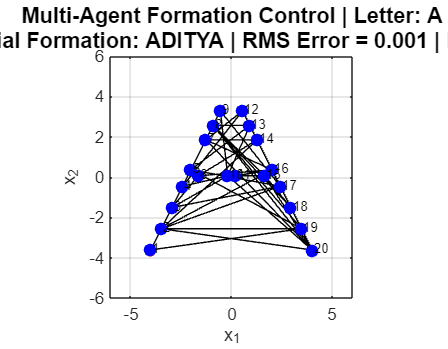



%% ============================================================
% 10. SEQUENTIAL LETTER FORMATION
% ============================================================

for letterIndex = 1:numLetters

    currentLetter = letters(letterIndex);

    target = formations{letterIndex};

    steps = round(T_letter/dt);

    fprintf(...
        'Forming letter %s ...\n',...
        currentLetter);


    for k = 1:steps

        %% Distributed formation controller

        x = formationController(...
            x,...
            target,...
            A,...
            kf,...
            kc,...
            dt);


        %% Time

        simulationTime = ...
            simulationTime + dt;


        %% Formation error

        currentError = sqrt(...
            mean(sum((x-target).^2,2)));


        errorHistory(end+1) = currentError;
        timeHistory(end+1) = simulationTime;


        %% Record video frame

        if mod(k,recordEvery) == 0

            frameCounter = frameCounter + 1;

            drawFormation(...
                x,...
                target,...
                A,...
                currentLetter,...
                sprintf(...
                'Sequential Formation: %s',...
                NAME),...
                currentError,...
                frameCounter);

            frame = getframe(fig);

            writeVideo(video,frame);

        end

    end

end



%% ============================================================
% 11. CLOSE VIDEO
% ============================================================

close(video);

fprintf('\n');
fprintf('============================================\n');

fprintf(' SIMULATION COMPLETED\n');

 SIMULATION COMPLETED


fprintf('============================================\n');

fprintf('Video saved as:\n');

Video saved as:


fprintf('ADITYA_formation.mp4\n');

ADITYA_formation.mp4


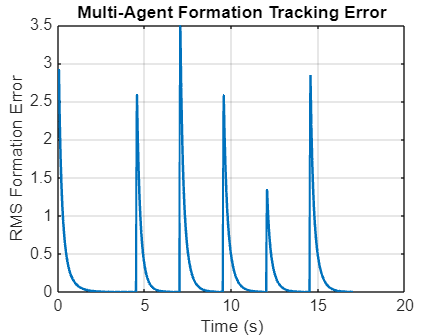



%% ============================================================
% 12. FORMATION ERROR PLOT
% ============================================================

figError = figure(...
    'Color','w',...
    'Name','Formation Error');

plot(...
    timeHistory,...
    errorHistory,...
    'LineWidth',1.5);

grid on;

xlabel('Time (s)');
ylabel('RMS Formation Error');

title(...
    'Multi-Agent Formation Tracking Error');

saveas(...
    figError,...
    'formation_error.png');


fprintf('Error plot saved as:\n');

Error plot saved as:


fprintf('formation_error.png\n');

formation_error.png


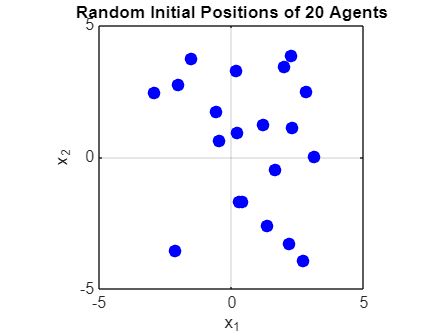



%% ============================================================
% 13. INITIAL POSITION PLOT
% ============================================================

figInitial = figure(...
    'Color','w',...
    'Name','Random Initial Positions');

plot(...
    initialPosition(:,1),...
    initialPosition(:,2),...
    'bo',...
    'MarkerFaceColor','b',...
    'MarkerSize',7);

grid on;
axis equal;

xlim([-5 5]);
ylim([-5 5]);

xlabel('x_1');
ylabel('x_2');

title('Random Initial Positions of 20 Agents');

saveas(...
    figInitial,...
    'initial_positions.png');



%% ============================================================
% FUNCTION 1
% DISTRIBUTED FORMATION CONTROLLER
% ============================================================

function xnew = formationController(...
    x,target,A,kf,kc,dt)

N = size(x,1);

velocity = zeros(N,2);

for i = 1:N

    %% -----------------------------------------
    % Formation attraction
    % ------------------------------------------

    formationTerm = ...
        -kf*(x(i,:) - target(i,:));


    %% -----------------------------------------
    % Communication with neighbors
    % ------------------------------------------

    communicationTerm = [0 0];

    neighbors = find(A(i,:) > 0);

    for j = neighbors

        % Current relative position
        currentRelative = ...
            x(i,:) - x(j,:);

        % Desired relative position
        desiredRelative = ...
            target(i,:) - target(j,:);

        % Relative-position error
        relativeError = ...
            currentRelative - desiredRelative;

        communicationTerm = ...
            communicationTerm - kc*relativeError;

    end


    %% -----------------------------------------
    % Total velocity
    % ------------------------------------------

    velocity(i,:) = ...
        formationTerm + communicationTerm;

end


%% Euler integration

xnew = x + dt*velocity;

end


%% ============================================================
% FUNCTION 2
% DRAW FORMATION
% ============================================================

function drawFormation(...
    x,target,A,currentLetter,sequenceText,...
    currentError,frameNumber)

N = size(x,1);

cla;

hold on;


%% ------------------------------------------------------------
% Draw communication edges
% ------------------------------------------------------------

for i = 1:N

    for j = i+1:N

        if A(i,j) == 1

            plot(...
                [x(i,1) x(j,1)],...
                [x(i,2) x(j,2)],...
                'k-',...
                'LineWidth',0.35);

        end

    end

end


%% ------------------------------------------------------------
% Desired formation
% ------------------------------------------------------------

plot(...
    target(:,1),...
    target(:,2),...
    'r.',...
    'MarkerSize',20);


%% ------------------------------------------------------------
% Current agent positions
% ------------------------------------------------------------

plot(...
    x(:,1),...
    x(:,2),...
    'bo',...
    'MarkerFaceColor','b',...
    'MarkerSize',7);


%% ------------------------------------------------------------
% Agent numbers
% ------------------------------------------------------------

for i = 1:N

    text(...
        x(i,1)+0.08,...
        x(i,2)+0.08,...
        sprintf('%d',i),...
        'FontSize',8);

end


%% ------------------------------------------------------------
% Axes
% ------------------------------------------------------------

axis equal;

xlim([-6 6]);
ylim([-6 6]);

grid on;

box on;

xlabel('x_1');
ylabel('x_2');


%% ------------------------------------------------------------
% Title
% ------------------------------------------------------------

title({...
    sprintf('Multi-Agent Formation Control | Letter: %s',...
    currentLetter),...
    sprintf('%s | RMS Error = %.3f | Frame %d',...
    sequenceText,currentError,frameNumber)},...
    'FontSize',13,...
    'FontWeight','bold');


drawnow;

end


%% ============================================================
% FUNCTION 3
% CREATE CAPITAL LETTER FORMATION
% ============================================================

function points = createLetter(letter,N)

letter = upper(letter);


%% ------------------------------------------------------------
% Define line segments
% ------------------------------------------------------------

switch letter


    %% ========================================================
    % A
    % ========================================================

    case 'A'

        segments = {

            [-2.5 -2.5; 0 2.5]

            [0 2.5; 2.5 -2.5]

            [-1.4 -0.2; 1.4 -0.2]

        };


    %% ========================================================
    % D
    % ========================================================

    case 'D'

        segments = {

            [-2.2 -2.5; -2.2 2.5]

            [-2.2 2.5; 0 2.5]

            [0 2.5; 2.2 1.2]

            [2.2 1.2; 2.2 -1.2]

            [2.2 -1.2; 0 -2.5]

            [0 -2.5; -2.2 -2.5]

        };


    %% ========================================================
    % I
    % ========================================================

    case 'I'

        segments = {

            [-2.0 2.5; 2.0 2.5]

            [0 2.5; 0 -2.5]

            [-2.0 -2.5; 2.0 -2.5]

        };


    %% ========================================================
    % T
    % ========================================================

    case 'T'

        segments = {

            [-2.5 2.5; 2.5 2.5]

            [0 2.5; 0 -2.5]

        };


    %% ========================================================
    % Y
    % ========================================================

    case 'Y'

        segments = {

            [-2.5 2.5; 0 0]

            [2.5 2.5; 0 0]

            [0 0; 0 -2.5]

        };


    otherwise

        error(...
            'Letter %s is not implemented.',letter);

end


%% ------------------------------------------------------------
% Generate many points on each line segment
% ------------------------------------------------------------

allPoints = [];


for s = 1:length(segments)

    P1 = segments{s}(1,:);
    P2 = segments{s}(2,:);

    distance = norm(P2-P1);

    numberOfSamples = ...
        max(20,ceil(distance*30));

    t = linspace(0,1,numberOfSamples)';

    segmentPoints = ...
        P1 + t.*(P2-P1);

    allPoints = ...
        [allPoints; segmentPoints];

end


%% ------------------------------------------------------------
% Remove duplicate points
% ------------------------------------------------------------

allPoints = unique(...
    round(allPoints,5),...
    'rows');


%% ------------------------------------------------------------
% Select exactly N points
% ------------------------------------------------------------

M = size(allPoints,1);

if M < N

    error(...
        'Not enough points available for letter %s.',letter);

end


index = round(...
    linspace(1,M,N));

points = allPoints(index,:);


%% ------------------------------------------------------------
% Center formation at origin
% ------------------------------------------------------------

points = ...
    points - mean(points,1);


%% ------------------------------------------------------------
% Normalize size
% ------------------------------------------------------------

maximum = max(abs(points(:)));

if maximum > 0

    points = ...
        4*points/maximum;

end

end